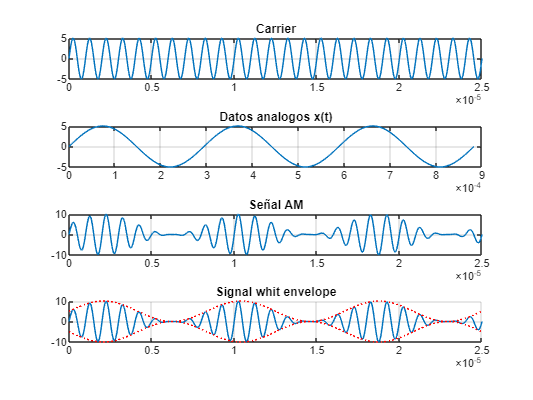

clc, clear all, close all
%-------------Input--------------
%Señal analoga
Ax = 5;
fx = 3400;
%Carrier 
Ac = 5;
fc = 1000e3;
pc = 0;
%Indice de modulacion
m = 0.2; % 0 <= m <= 1
%-----Proceso
%datos analogos
Tx = 1/fx;
tx = linspace(0,3*Tx,500);
xt = Ax *sin(2*pi*fx*tx);
%carrier
Tc = 1/fc;
tc = linspace(0,25*Tc,500);
carrier = Ac*sin(2*pi*fc*tc);
AM = (1+m*xt).*carrier;
figure(1)
subplot(4,1,1), plot(tc, carrier), title('Carrier'), grid on
subplot(4,1,2), plot(tx, xt), title('Datos analogos x(t)'), grid on
subplot(4,1,3), plot(tc, AM), title('Señal AM'), grid on
subplot(4,1,4)
hold on
plot(tc, AM), title('Signal whit envelope'), grid on
plot(tc,xt+Ac, ':r')
plot(tc,-xt-Ac, ':r')
hold off